% This file generates an uncertain plant model based on the Qube servo
% scripts from Quanser.  I am adding uncertainty to the pendulum itself

%% Motor
% Resistance
Rm = 8.4;
% Current-torque (N-m/A)
kt = 0.042;
% Back-emf constant (V-s/rad)
km = 0.042;
%
%% Rotary Arm
% Mass (kg)
Mr = 0.095;
% Total length (m)
Lr = 0.085;
% Moment of inertia about pivot (kg-m^2)
Jr = Mr*Lr^2/12;
% Equivalent Viscous Damping Coefficient (N-m-s/rad)
Dr = 0;
%
%% Pendulum Link
% Mass (kg)
Mp = ureal('M',0.024,'Percentage',20);
% Total length (m)
Lp = 0.129;
% Moment of inertia about pivot (kg-m^2)
Jp = Mp*Lp^2/12;
% Equivalent Viscous Damping Coefficient (N-m-s/rad)
Dp = 0;
% Gravity Constant
g = 9.81;

% State Space Representation
Jt = Jr*Jp + Mp*(Lp/2)^2*Jr + Jp*Mp*Lr^2;
A = [0 0 1 0;
     0 0 0 1;
     0 Mp^2*(Lp/2)^2*Lr*g/Jt -Dr*(Jp+Mp*(Lp/2)^2)/Jt -Mp*(Lp/2)*Lr*Dp/Jt;
     0 Mp*g*(Lp/2)*(Jr+Mp*Lr^2)/Jt -Mp*(Lp/2)*Lr*Dr/Jt -Dp*(Jr+Mp*Lr^2)/Jt];

B = [0; 0; (Jp+Mp*(Lp/2)^2)/Jt; Mp*(Lp/2)*Lr/Jt];
C = eye(2,4);  %Measure only the angles
D = zeros(2,1);

% Add actuator dynamics
B = kt * B / Rm;
A(3,3) = A(3,3) - kt*kt/Rm*B(3);
A(4,3) = A(4,3) - kt*kt/Rm*B(4);

% Load into state-space system
Gunc = minreal(ss(A,B,C,D));
G = Gunc.NominalValue;

# Q3(A)

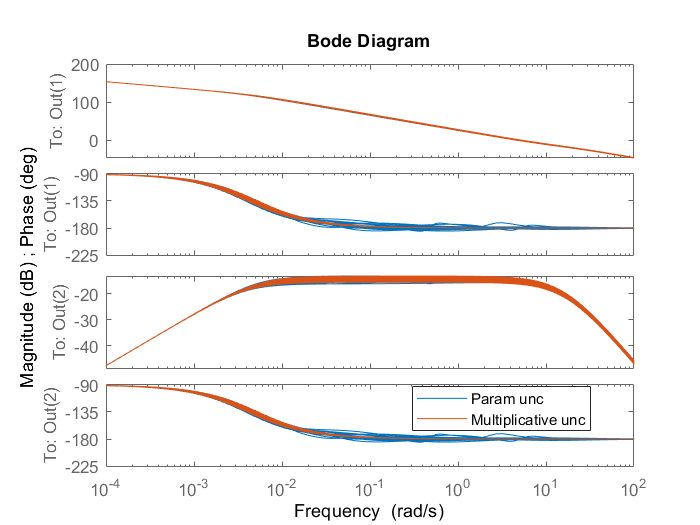

G_uncertain = usample(Gunc,100);
[P1,info_1] = ucover(G_uncertain(1),G(1),4,'OutputMult');
[P2,info_2] = ucover(G_uncertain(2),G(2),4,'OutputMult');
P = [P1;P2];
bode(P,Gunc)
legend('Param unc','Multiplicative unc', "Location","best")

P = minreal(P);

4 states removed.


# Q3(B)

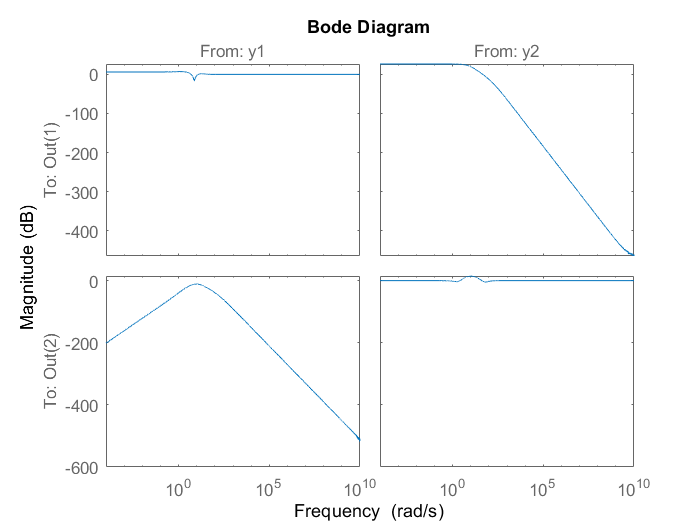

QXU = blkdiag(diag([100 100 1 1]),0.1);
QWV = blkdiag(100*eye(4),0.1*eye(2));  %Just for demo

%QXU = blkdiag(diag([100 100 1 1]),1);
%QWV = blkdiag(100*eye(4),0.1*eye(2));  %Just for demo

K = lqg(G,QXU,QWV);

S_LQG = eye(2)-feedback(P*K,-eye(2));
S_LQG_nom = eye(2)-feedback(G*K,-eye(2));

Wt = minreal([info_1.W1 0;0 info_2.W1]);
W = logspace(-4,10,1e4);
S_LQG_FRD = frd(S_LQG.NominalValue,W);
S_LQG_FRD_1 = S_LQG_FRD(1,1);
S_LQG_FRD_2 = S_LQG_FRD(2,2);
bodemag(S_LQG_FRD)

Wp = minreal([1/fitmagfrd(S_LQG_FRD_1,4) 0;0 1/fitmagfrd(S_LQG_FRD_2,4)]);

2 states removed.


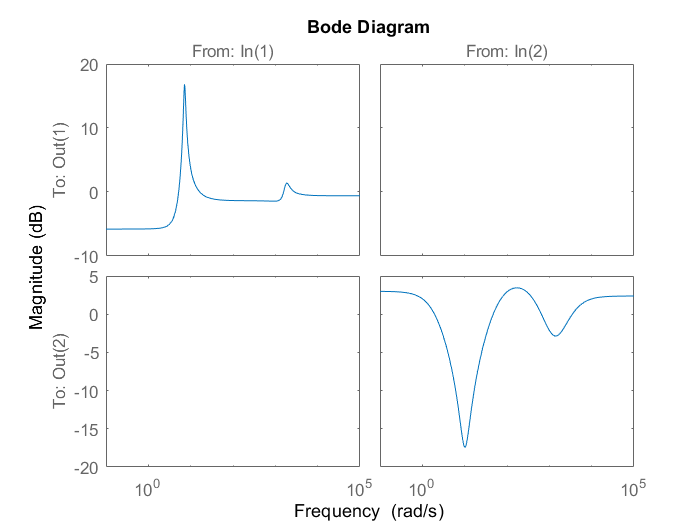

bodemag(Wp)

[K_inf,CL,gamma,info] = mixsyn(G,Wp,1/1000,Wt);

Sinf = eye(2) - feedback(P*K_inf,eye(2));

# Q3(c)

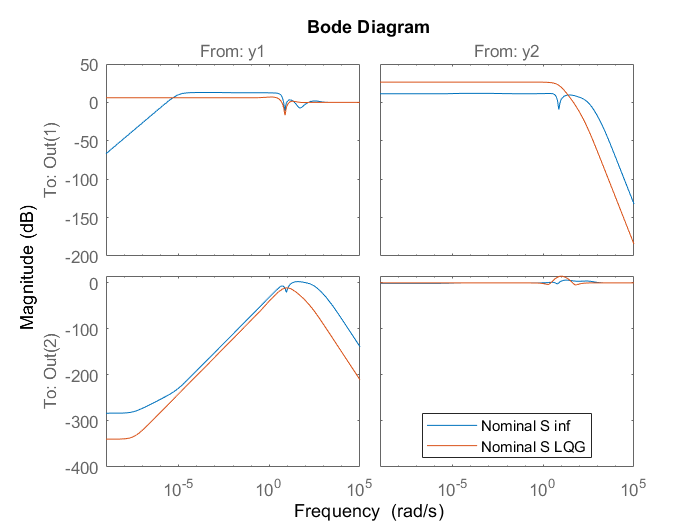

Sinf_nom = eye(2) - feedback(G*K_inf,eye(2));
bodemag(Sinf_nom,S_LQG_nom)
legend("Nominal S inf","Nominal S LQG","Location","best")

# Q3(d)

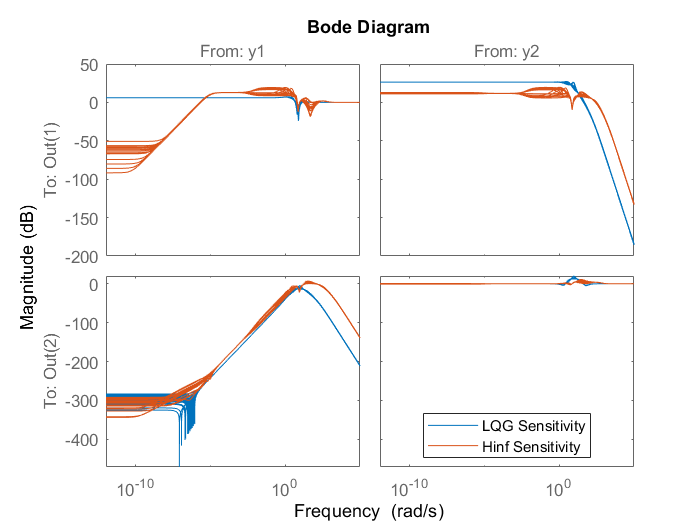

bodemag(S_LQG,Sinf)
legend("LQG Sensitivity","Hinf Sensitivity","Location","best")

isstable(Sinf)

ans = logical
   1


[STABMARG, info] = robstab(Sinf);
mu = 1/STABMARG.LowerBound

mu = 0.5692

[STABMARG, info] = robstab(S_LQG);
mu = 1/STABMARG.LowerBound

mu = 0.5859

Yes. The Hinf synthesishas increased the robust stability of the sensitivity function. We can see that the values of mu obtained using robstab is more in case of LQG than Hinf..